simOut = out.MotorPowerOut(1);
out_ref = out.ScopeData;
P = simOut.signals.values   ;     % your instantaneous power vector
t = simOut.time;

p = out_ref;
rack_pos = squeeze(out_ref{1}.Values.Data);
ref_pos = squeeze(out_ref{2}.Values.Data);

P_peak = max(P)

P_peak = 153.3204

P_rms = rms(P)

P_rms = 69.1116

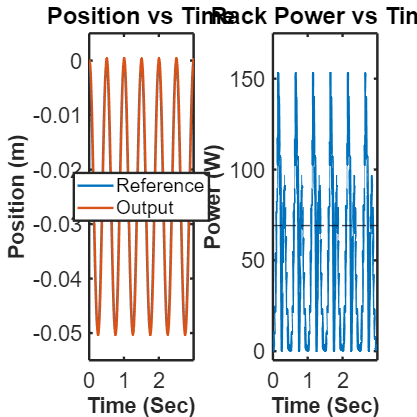


figure
subplot(1, 2, 1)
plot(t,ref_pos)
hold on
plot(t,rack_pos)
title("Position vs Time")
xlabel("Time (Sec)")
ylabel("Position (m)")
legend("Reference", "Output")
ylim([-0.055, 0.005])

subplot(1, 2, 2)
plot(t,P)
hold on;
yline(P_rms, 'k--')
title("Rack Power vs Time")
xlabel("Time (Sec)")
ylabel("Power (W)")
ylim([-5, 175])
improvePlot